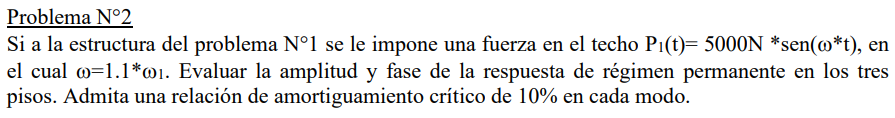

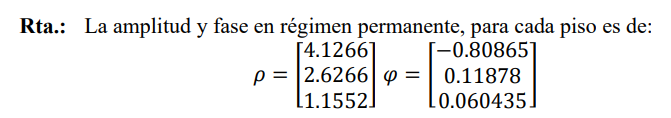

%% Problema 2 - Tp7
%Mismo sistema que en el ejercicio 1, pero ahora el sistema está sometido a
%una fuerza senoidal aplicada en la masa 1
%P(t)=5000 N * sin(wp*t)
%donde wp=1.1*w1

clc; clear;


%% ---------------- DATOS DEL SISTEMA (EJ1) -----------------------

%Masas
m1=2;
m2=2;
m3=2;
M = diag([m1,m2,m3]);

%Rigidez
k1=600;
k2=1200;
k3=2400;
K = [k1 -k1 0;
    -k1 k1+k2 -k2;
    0 -k2 k2+k3];

%Condiciones iniciales
x0 = [0.3; -0.8; 0.3]; %Desplazamientos iniciales
dx0 = [0; 0; 0] ; %Velocidades iniciales

%Tiempo para graficar
tf=10;
dt=0.01;
t=0:dt:tf;

%Relacion de amortiguamiento crítico
zeta = [0.1; 0.1; 0.1];

%% ------------------ AUTOVECTORES Y AUTOVALORES ------------------

[V,lambda] = eig(K,M);
w = diag(sqrt(lambda))

w =    11.6511
   27.4598
   45.9370



%% ----------------- FUERZA ---------------------------------------
Po = 1124/100; %1.124; %5000; %[N]
wp = 1.1*w(1);

%Vector fuerza
P = zeros(length(M),length(t));
P(1,:) = Po.*sin(wp*t);

%% ----------------- MATRICES MODALES -----------------------------

Mmodal = V' * M * V;
Kmodal = V' * K * V;
Y0 = V' * M * x0;                   %desplazamiento inicial en coordenadas modales
dY0 = V' * M * dx0;                 %velocidad inicial en coordenadas modales
Cmodal = 2*zeta.*w.*eye(size(M));
Pmodal = V' * P;                    %Paso fuerza a coordenadas modales
PoModal = V' * [Po; 0; 0];          %Paso las amplitudes de las fuerzas a coordenadas modales

%% ----------------- SOLUCION A LA EDO ----------------------------

%Tenemos un sistema de tipo Mmodal*y''+Cmodal*y'+Kmodal=Pmodal
%Cuya solución es y(t) = ytransitoria + ypermanente
%PERO EL EJERCICIO PIDE SOLO EVALUAR LA RESPUESTA PERMANENTE

%la respuesta permanente es
%ypermanente = ro * cos(wp*t-phi) donde ro es la amplitud y phi es el
%angulo de atraso
%ro(j)=Fo(j)/(k(j)*sqrt( (1-beta^2)^2 + (2*zitta*beta)^2 ))
%phi(j)=atan(2*zitta*beta/(1-beta^2));

%Cosas que necesito para calcular la solucion
e=exp(1);
wd = w.*sqrt(1-zeta.^2); %frecuencia natural del sistema amortiguado
beta = zeros(length(w),1);
phi = zeros(length(w),1);
rho = zeros(length(w),1);
D = zeros(length(w),1);

for i=1:length(w)
    beta(i)=wp/w(i);
    D(i) = 1/sqrt( (1-beta(i)^2)^2 + (2*zeta(i)*beta(i))^2 );
    phi(i)=atan(2*zeta(i)*beta(i)/(1-beta(i)^2));
    rho(i)=PoModal(i)/Kmodal(i,i)*D(i);
end

Y = zeros(length(w), length(t));

for i = 1:length(w)    
    Y(i,:) = rho(i,:).*sin(wp*t-phi(i));
end


rhoX = V * rho

rhoX =     0.1040
    0.0520
    0.0182


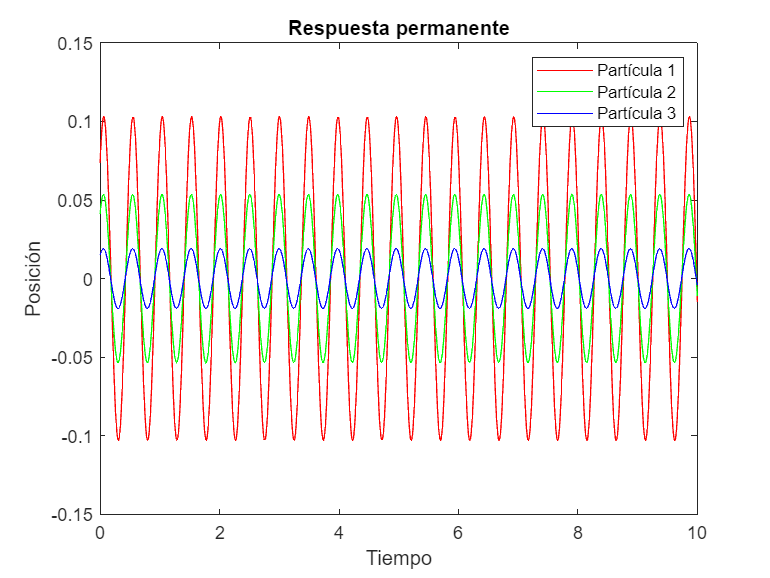


%Ahora paso de coordenadas modales a geométricas
X = V * Y;

% Graficar las posiciones de las partículas
figure(1)
plot(t, X(1,:), 'r', t, X(2,:), 'g', t, X(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta permanente');


rho

rho =     0.1664
    0.0067
    0.0003


phi

phi =    -0.8086
    0.1188
    0.0604


Xmax1 = max(X(1,:))

Xmax1 = 0.1031

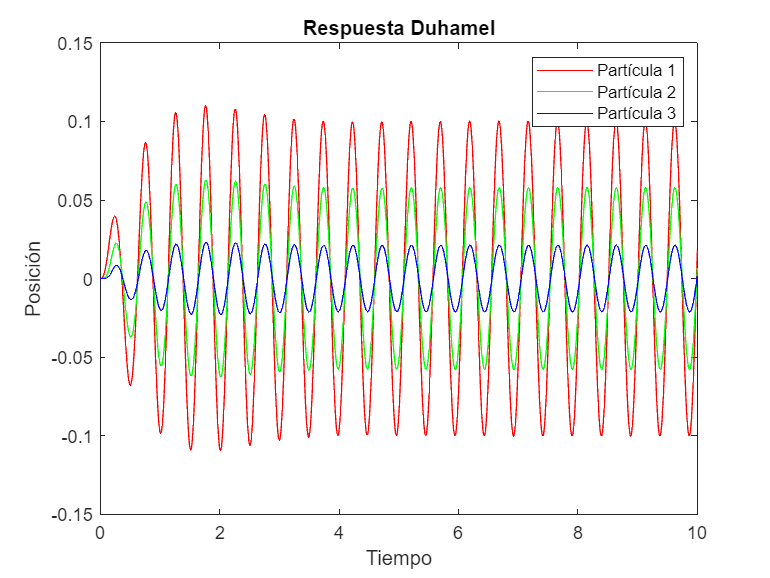


%% --------- RESOLUCION USANDO DUHAMEL-------------------

yc= zeros(length(w), length(t));
ys= zeros(length(w), length(t));
A = zeros(length(w), length(t)); %Se usa en la integral de duhamel
B = zeros(length(w), length(t)); %Se usa en la integral de duhamel

Y2=zeros(length(w),length(t));

wd=w.*sqrt(1-zeta.^2);

for i=1:length(w)
    yc(i,:) = Pmodal(i,:).*cos(wd(i)*t); %Se usa en la integral duhamel
    ys(i,:) = Pmodal(i,:).*sin(wd(i)*t); %Se usa en la integral de duhamel
    
    for j=2:length(t)
        A(i,j) = A(i,j-1)*e.^(-zeta(i)*w(i)*dt) + dt/(2*wd(i)*Mmodal(i,i)) * (yc(i,j-1)*e.^(-zeta(i)*w(i)*dt) + yc(i,j));
        B(i,j) = B(i,j-1)*e.^(-zeta(i)*w(i)*dt) + dt/(2*wd(i)*Mmodal(i,i)) * (ys(i,j-1)*e.^(-zeta(i)*w(i)*dt) + ys(i,j));
    end
    
    Y2(i,:) = A(i,:).*sin(wd(i)*t) - B(i,:).*cos(wd(i)*t);
end

X2=V*Y2;

% Graficar las posiciones de las partículas
figure(2)
plot(t, X2(1,:), 'r', t, X2(2,:), 'g', t, X2(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2', 'Partícula 3');
title('Respuesta Duhamel');